# Build Map from 2-D Lidar Scans Using SLAM

This example shows how to implement the SLAM algorithm on a series of 2-D lidar scans using scan processing and pose graph optimization (PGO). The goal of this example is to estimate the trajectory of the robot and build a map of the environment.

*SLAM* stands for simultaneous localization and mapping.

- *Localization* — Estimating the pose of a robot in a known environment.

- *Mapping *— Building the map of an unknown environment from a known robot pose and sensor data.

In the SLAM process, a robot creates a map of an environment while localizing itself. SLAM has a wide range of applications in robotics, self-driving cars, and UAVs.

In offline SLAM, a robot steers through an environment and records the sensor data. The SLAM algorithm processes this data to compute a map of the environment. The map is stored and used for localization, path-planning during the actual robot operation. 

This example uses a 2-D offline SLAM algorithm. The algorithm incrementally processes recorded lidar scans and builds a pose graph to create a map of the environment. To overcome the drift accumulated in the estimated robot trajectory, the example uses scan matching to recognize previously visited places and then uses this loop closure information to optimize poses and update the map of the environment. To optimize the pose graph, this example uses a 2-D pose graph optimization function from Navigation Toolbox™.

In this example, you learn how to:

- Estimate robot trajectory from a series of scans using scan registration algorithms.

- Optimize the drift in the estimated robot trajectory by identifying previously visited places (loop closures).

- Visualize the map of the environment using scans and their absolute poses.

## Load Laser Scans

This example uses data collected in an indoor environment using a Jackal™ robot from Clearpath Robotics™. The robot is equipped with a SICK™ TiM-511 laser scanner with a maximum range of 10 meters. Load the `wareHouse.mat` file containing the laser scans into the workspace.

data = load("wareHouse.mat");
scans = data.wareHouseScans;

disp(scans)

    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lid

## Estimate Robot Trajectory

Create a [`lidarscanmap`](docid:lidar_ref#mw_113f5aef-b447-4e6a-bfb7-f2f3256e00e3) object. Using this object, you can:

- Store and add lidar scans incrementally.

- Detect, add, and delete loop closures.

- Find and update the absolute poses of the scans.

- Generate and visualize a pose graph.

Specify the maximum lidar range and grid resolution values. You can modify these values to fine-tune the map of the environment. Use these values to create the lidar scan map.

maxLidarRange = 8;
gridResolution = 20;
mapObj = lidarscanmap(gridResolution,maxLidarRange);

Incrementally add scans from the input data to the lidar scan map object by using the [`addScan`](docid:lidar_ref#mw_436dfe76-c72b-42e1-8e32-8efa7262eec5) function. This function rejects scans if they are too close to consecutive scans.

for i = 1:numel(scans)
    isScanAccepted = addScan(mapObj,scans{i});
     if ~isScanAccepted
        continue;
     end
end

Reconstruct the scene by plotting the scans and poses tracked by the lidar scan map.

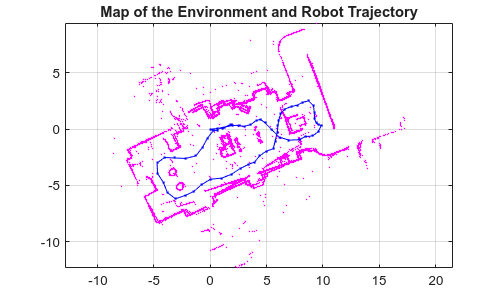

hFigMap = figure;
axMap = axes(Parent=hFigMap);
show(mapObj,Parent=axMap);
title(axMap,"Map of the Environment and Robot Trajectory")

Notice that the estimated robot trajectory drifts over time. The drift can be due to any of these reasons:

- Noisy scans from the sensor, without sufficient overlap.

- Absence of significant features in the environment.

- An inaccurate initial transformation, especially when rotation is significant

Drift in the estimated trajectory results in an inaccurate map of the environment.

## Drift Correction

Correct the drift in trajectory by accurately detecting the *loops*, which are the places the robot returns to, after previously visiting. Add the loop closure edges to the [`lidarscanmap`](docid:lidar_ref#mw_113f5aef-b447-4e6a-bfb7-f2f3256e00e3) object to correct the drift in trajectory during pose graph optimization.

### Loop Closure Detection

*Loop closure detection* determines whether, for a given scan, the robot has previously visited the current location. The search consists of matching the current scan against the previous scans around the current robot location, within the specified radius `loopClosureSearchRadius`. Accept a scan as a match if the match score is greater than the specified threshold `loopClosureThreshold`. 

You can detect loop closures by using the [`detectLoopClosure`](docid:lidar_ref#mw_396bbc90-2546-41ce-9980-5f02ffc10ba1) function of the [`lidarscanmap`](docid:lidar_ref#mw_113f5aef-b447-4e6a-bfb7-f2f3256e00e3) object and the add them to the map object by using the [`addLoopClosure`](docid:lidar_ref#mw_6ebaae81-1e58-412e-868e-eab20326412a) function.

You can increase the `loopClosureThreshold` value to avoid false positives in loop closure detection, but the function can still return bad matches in environments with similar or repeated features. To address this, increase the `loopClosureSearchRadius` value to search a larger radius around the current scan for loop closures, though this increases computation time. 

You can also specify the number of loop closure matches `loopClosureNumMatches`. All of these parameters help in fine-tuning the loop closure detections.

loopClosureThreshold = 110;
loopClosureSearchRadius = 2;
loopClosureNumMatches = 1;
mapObjLoop = lidarscanmap(gridResolution,maxLidarRange);
for i = 1:numel(scans)
    isScanAccepted = addScan(mapObjLoop,scans{i});
    % Detect loop closure if scan is accepted
     if isScanAccepted
         [relPose,matchScanId] = detectLoopClosure(mapObjLoop, ...
             MatchThreshold=loopClosureThreshold, ...
             SearchRadius=loopClosureSearchRadius, ...
             NumMatches=loopClosureNumMatches);
         % Add loop closure to map object if relPose is estimated
         if ~isempty(relPose)
            addLoopClosure(mapObjLoop,matchScanId,i,relPose);
         end
     end
end

### Optimize Trajectory

Create a pose graph object from the drift-corrected lidar scan map by using the [`poseGraph`](docid:lidar_ref#mw_a18b4cdc-1b1b-4fbb-aaa5-e247b94ba33e) function. Use the [`optimizePoseGraph`](docid:nav_ref#mw_ead0d07b-dffc-4389-93ef-8fa1432c60cb) function to optimize the pose graph. 

pGraph = poseGraph(mapObjLoop);
updatedPGraph = optimizePoseGraph(pGraph);

Extract the optimized absolute poses from the pose graph by using the [`nodeEstimates`](docid:nav_ref#mw_086a3020-0aae-4443-81cb-7b42894f7c98) function, and update the trajectory to build an accurate map of the environment.

optimizedScanPoses = nodeEstimates(updatedPGraph);
updateScanPoses(mapObjLoop,optimizedScanPoses);

## Visualize Results

Visualize the change in robot trajectory before and after pose graph optimization. The red lines represent loop closure edges.

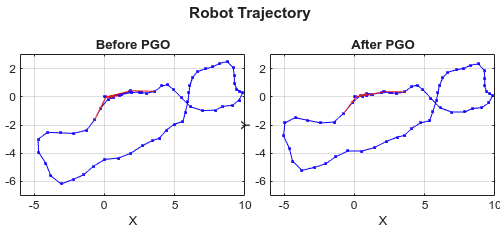

hFigTraj = figure(Position=[0 0 900 450]);

% Visualize robot trajectory before optimization
axPGraph = subplot(1,2,1,Parent=hFigTraj);
axPGraph.Position = [0.04 0.1 0.45 0.8];
show(pGraph,IDs="off",Parent=axPGraph);
title(axPGraph,"Before PGO")

% Visualize robot trajectory after optimization
axUpdatedPGraph = subplot(1,2,2,Parent=hFigTraj);
axUpdatedPGraph.Position = [0.54 0.1 0.45 0.8];
show(updatedPGraph,IDs="off",Parent=axUpdatedPGraph);
title(axUpdatedPGraph,"After PGO")
axis([axPGraph axUpdatedPGraph],[-6 10 -7 3])
sgtitle("Robot Trajectory",FontWeight="bold")

Visualize the map of the environment and robot trajectory before and after pose graph optimization.

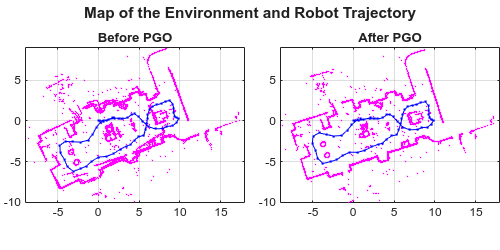

hFigMapTraj = figure(Position=[0 0 900 450]);

% Visualize map and robot trajectory before optimization
axOldMap = subplot(1,2,1,Parent=hFigMapTraj);
axOldMap.Position = [0.05 0.1 0.44 0.8];
show(mapObj,Parent=axOldMap);
title(axOldMap,"Before PGO")

% Visualize map and robot trajectory after optimization
axUpdatedMap = subplot(1,2,2,Parent=hFigMapTraj);
axUpdatedMap.Position = [0.56 0.1 0.44 0.8];
show(mapObjLoop,Parent=axUpdatedMap);
title(axUpdatedMap,"After PGO")
axis([axOldMap axUpdatedMap],[-9 18 -10 9])
sgtitle("Map of the Environment and Robot Trajectory",FontWeight="bold")

%Create a lidarSLAM object and set the map resolution and the max lidar range.
%This example uses a Jackal™ robot from Clearpath Robotics™. The robot is equipped with a SICK™ TiM-511 laser scanner with a max range of 10 meters. Set the max lidar range slightly smaller than the max scan range (8m), as the laser readings are less accurate near max range. Set the grid map resolution to 20 cells per meter, which gives a 5cm precision.


maxLidarRange = 8; %smaller than 10 meters
mapResolution = 20; %Set the max lidar range slightly smaller than the max scan range (8m), as the laser readings are less accurate near max range. Set the grid map resolution to 20 cells per meter, which gives a 5cm precision.
slamAlg = lidarSLAM(mapResolution, maxLidarRange);

%The following loop closure parameters are set empirically. Using higher loop closure threshold helps reject false positives in loop closure identification process.
%However, keep in mind that a high-score match may still be a bad match. For example, scans collected in an environment that has similar or repeated features are more
% likely to produce false positives. Using a higher loop closure search radius allows the algorithm to search a wider range of the map around current pose estimate for loop closures.

slamAlg.LoopClosureThreshold = 210;  
slamAlg.LoopClosureSearchRadius = 8;

%Incrementally add scans to the slamAlg object. Scan numbers are printed if added to the map. The object rejects scans if the distance between scans is too small.
%Add the first 10 scans first to test your algorithm.
for i=1:10
    [isScanAccepted, loopClosureInfo, optimizationInfo] = addScan(slamAlg, scans{i});
    if isScanAccepted
        fprintf('Added scan %d \n', i);
    end
end

Added scan 1 
Added scan 2 
Added scan 3 
Added scan 4 
Added scan 5 
Added scan 6 
Added scan 7 
Added scan 8 
Added scan 9 
Added scan 10 


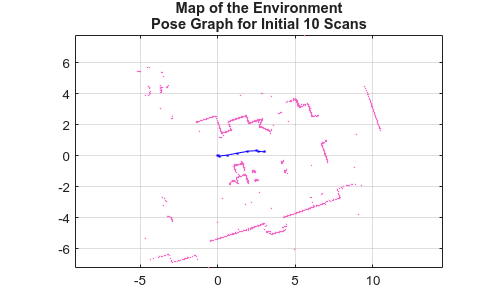

% Reconstruct the scene by plotting the scans and poses tracked by the slamAlg.
figure;
show(slamAlg);
title({'Map of the Environment','Pose Graph for Initial 10 Scans'});

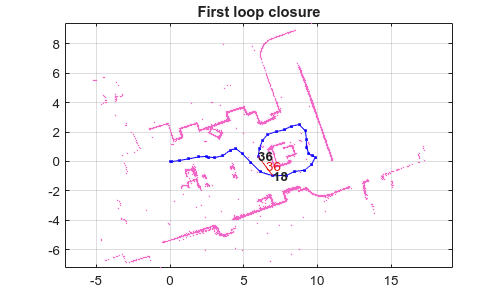

%Observe the Effect of Loop Closures and the Optimization Process
%Continue to add scans in a loop. Loop closures should be automatically detected as the robot moves.
%Pose graph optimization is performed whenever a loop closure is identified. The output optimizationInfo has a field, IsPerformed, that indicates when pose graph optimization occurs.

firstTimeLCDetected = false;

figure;
for i=10:length(scans)
    [isScanAccepted, loopClosureInfo, optimizationInfo] = addScan(slamAlg, scans{i});
    if ~isScanAccepted
        continue;
    end
    % visualize the first detected loop closure, if you want to see the
    % complete map building process, remove the if condition below
    if optimizationInfo.IsPerformed && ~firstTimeLCDetected
        show(slamAlg, 'Poses', 'off');
        hold on;
        show(slamAlg.PoseGraph); 
        hold off;
        firstTimeLCDetected = true;
        drawnow
    end
end
title('First loop closure');

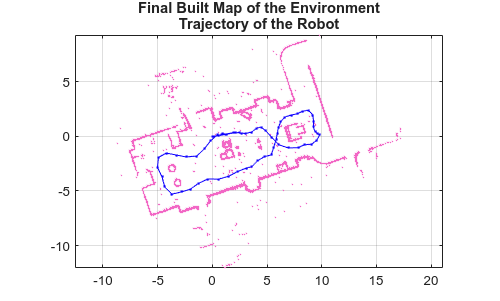

% Visualize the Constructed Map and Trajectory of the Robot
% Plot the final built map after all scans are added to the slamAlg object.
% Though the previous for loop only plotted the initial closure, all the scans were added.

figure
show(slamAlg);
title({'Final Built Map of the Environment', 'Trajectory of the Robot'});

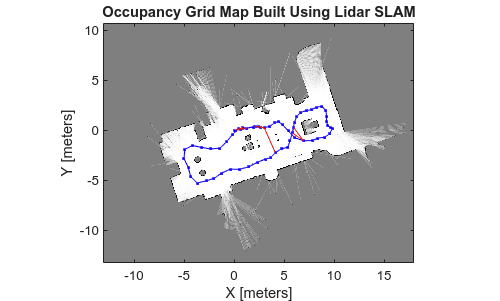

% Build Occupancy Grid Map
% The optimized scans and poses can be used to generate a occupancyMap,
% which represents the environment as a probabilistic occupancy grid.
[scans, optimizedPoses]  = scansAndPoses(slamAlg);
map = buildMap(scans, optimizedPoses, mapResolution, maxLidarRange);
figure; 
show(map);
hold on
show(slamAlg.PoseGraph, 'IDs', 'off');
hold off
title('Occupancy Grid Map Built Using Lidar SLAM');

*Copyright 2020-2022 The MathWorks, Inc.*